# Intersecting Lines

This is a demonstration of finding the intersect of two lines which are defined individually by two points - a start and an end point. The resulted intersect is the analytical solution and will return an intersect provided the two lines are not parallel.

figure(1)
clf
hold on

## Line 1

Define two points creating the first line

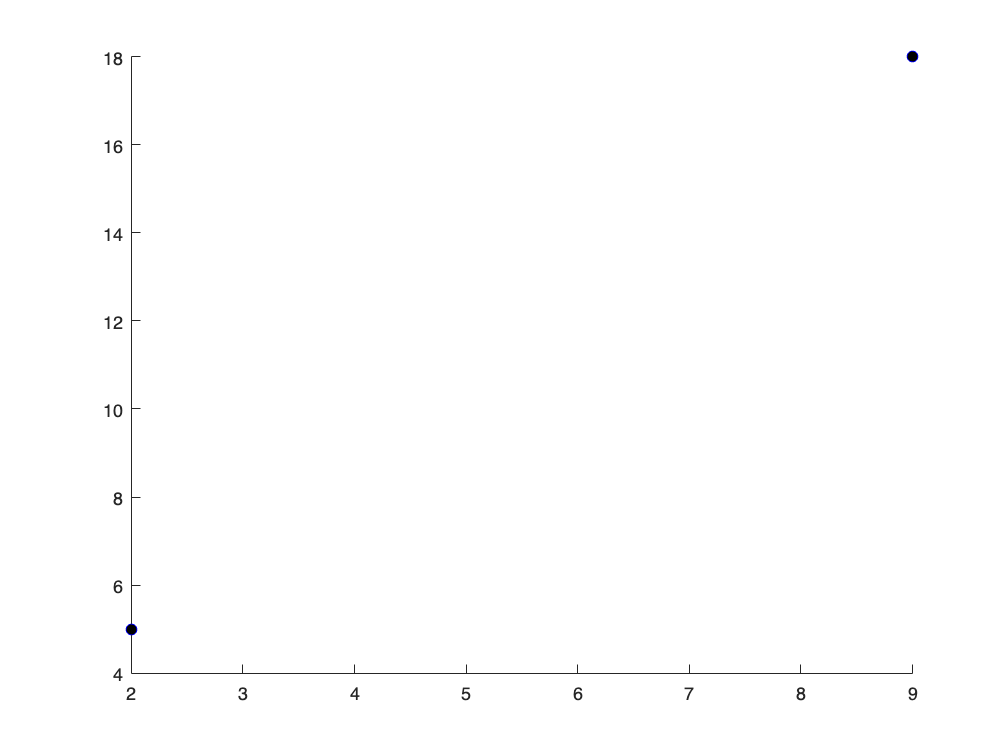

x11 = 2;
y11 = 5;

x12 = 9;
y12 = 18;   

scatter(x11, y11, 'bo', 'markerfacecolor', 'k')
scatter(x12, y12, 'bo', 'markerfacecolor', 'k')

Using $y=\textrm{mx}+c$, find the gradient and y-intersect for the line


$$\textrm{Gradient}:m_1 =\frac{y_{12} -y_{11} }{x_{12} -x_{11} }$$



$$y-\textrm{interect}:c_1 =y_{11} -m_1 x_{11}$$


m1 = (y12 - y11) / (x12 - x11);
c1 = y11 - m1 * x11;

Create the line for x values in the range 0 to 20.

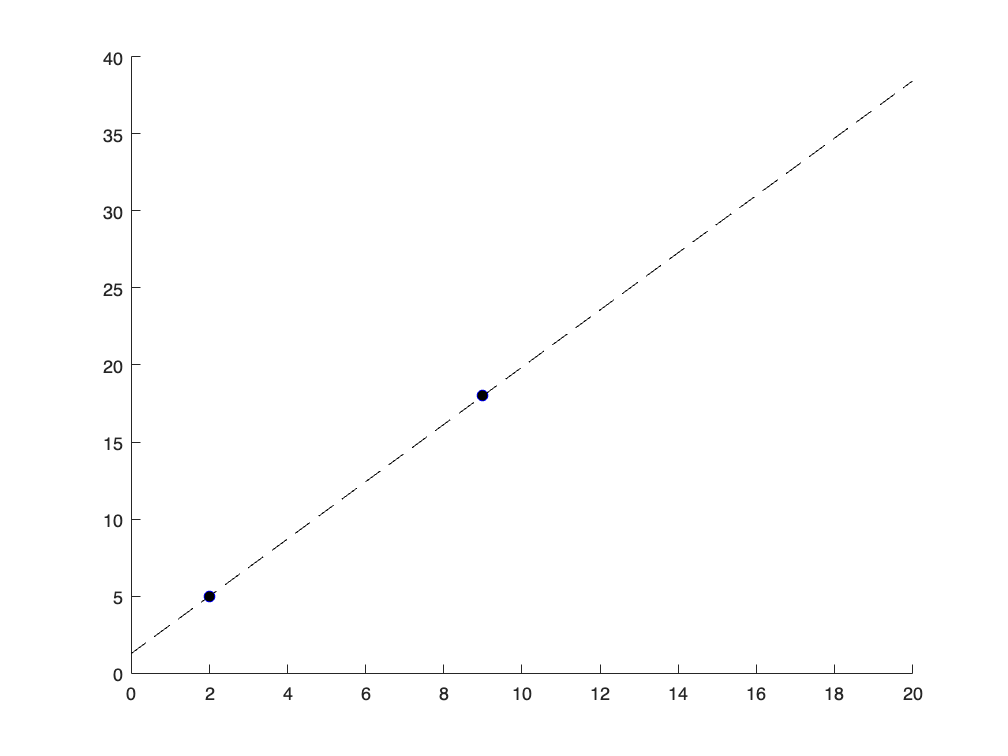

x1 = 0:1:20;
y1 = m1*x1 + c1;

plot(x1,y1, 'linewidth', 0.5, 'color', 'black', 'LineStyle', '--')

## Line 2

Repeat the procedure for a second line

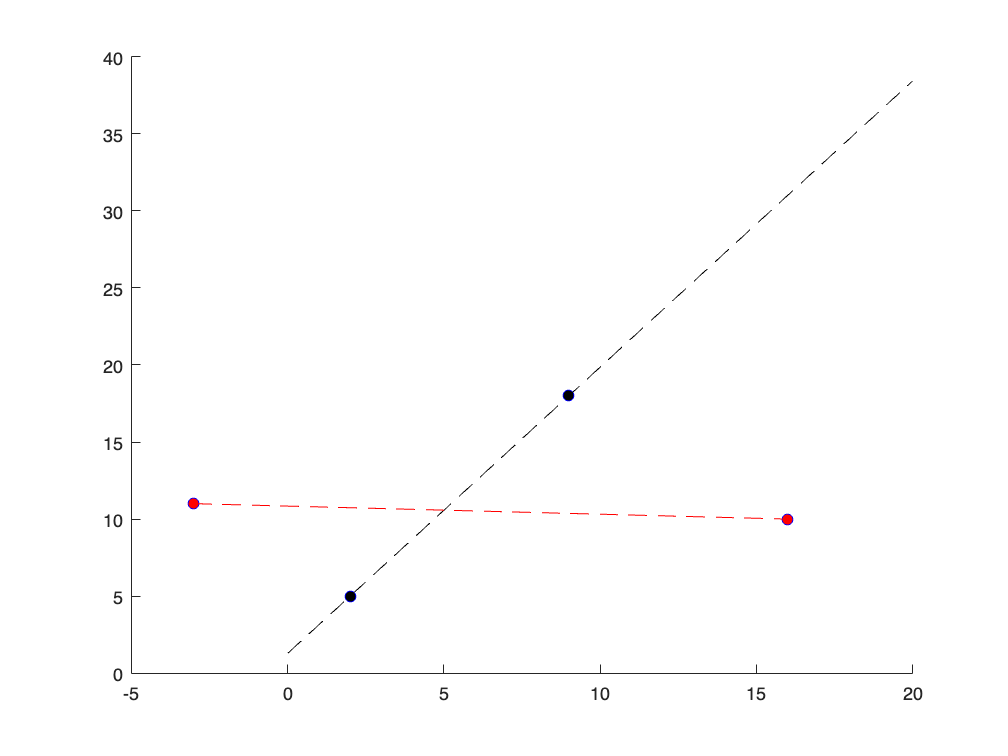

x21 = -3;
y21 = 11;
x22 = 16;
y22 = 10;

scatter(x21, y21, 'bo', 'markerfacecolor', 'red')
scatter(x22, y22, 'bo', 'markerfacecolor', 'red')

m2 = (y22 - y21) / (x22 - x21);
c2 = y21 - m2 * x21;

x2 = x21:0.1:x22;
y2 = m2.*x2 + c2;

plot(x2,y2, 'linewidth', 0.5, 'color', 'red', 'LineStyle', '--')

## Find the Intersect

From $y=\textrm{mx}+c$ we can convert to the form $\textrm{Ax}+\textrm{Bx}+C=0$. We will perform this operation for each point forming each line, creating simulataneous equations which can then be solved. Therefore,

${\textrm{Ax}}_{11} +{\textrm{By}}_{11} +c_1 =0$ and ${\textrm{Ax}}_{12} +B_{12} +c_1 =0$

$B=\frac{{\textrm{Ax}}_{11} +c_1 }{y_{11} }$ and $B=\frac{{\textrm{Ax}}_{12} +c_{1\;} }{y_{12} }$


$$\frac{{\textrm{Ax}}_{11} +c_1 }{y_{11} }=\frac{{\textrm{Ax}}_{12} +c_{1\;} }{y_{12} }\to y_{11} {\textrm{Ax}}_{11} +c_1 y_{11} ={\textrm{Ax}}_{12} y_{11} +c_1 y_{12}$$



$$A\left(y_{12} x_{11} -y_{11} x_{12} \right)=c_1 \left(y_{12} -y_{11} \right)$$



$$A=\frac{c_1 \left(y_{12} -y_{11} \right)}{\left(y_{12} x_{11} -y_{11} x_{12} \right)}$$


We can now solve this for the first line

a1 = (c1*y11 - c1*y12) / (x11*y12 - x12*y11);

From the equation for $A$it is apparent that if the gradient is 0, the equation will have a 0 on the numerator. We can catch this error by checking for a NaN value and setting A = 1 in this instance. 

if isnan(a1)
    a1 = 1;
end

We then solve for B using ${\textrm{Ax}}_{11} +{\textrm{By}}_{11} +c_1 =0$

b1 = (a1*x12 + c1) / y12;

And repeat this process for the second line

a2 = (c2*y21 - c2*y22) / (x21*y22 - x22*y21);
if isnan(a2)
    a2 = 1;
end
b2 = (a2*x22 + c2) / y22;

We can then solve to find the intersection 


$$\left(x,y\right)=\left\lbrack \begin{array}{cc}
\frac{b_1 c_2 -b_2 c_1 }{a_1 b_2 -a_2 b_1 } & \frac{a_1 c_2 -a_2 c_1 }{a_1 b_2 -a_2 b_1 }
\end{array}\right\rbrack$$


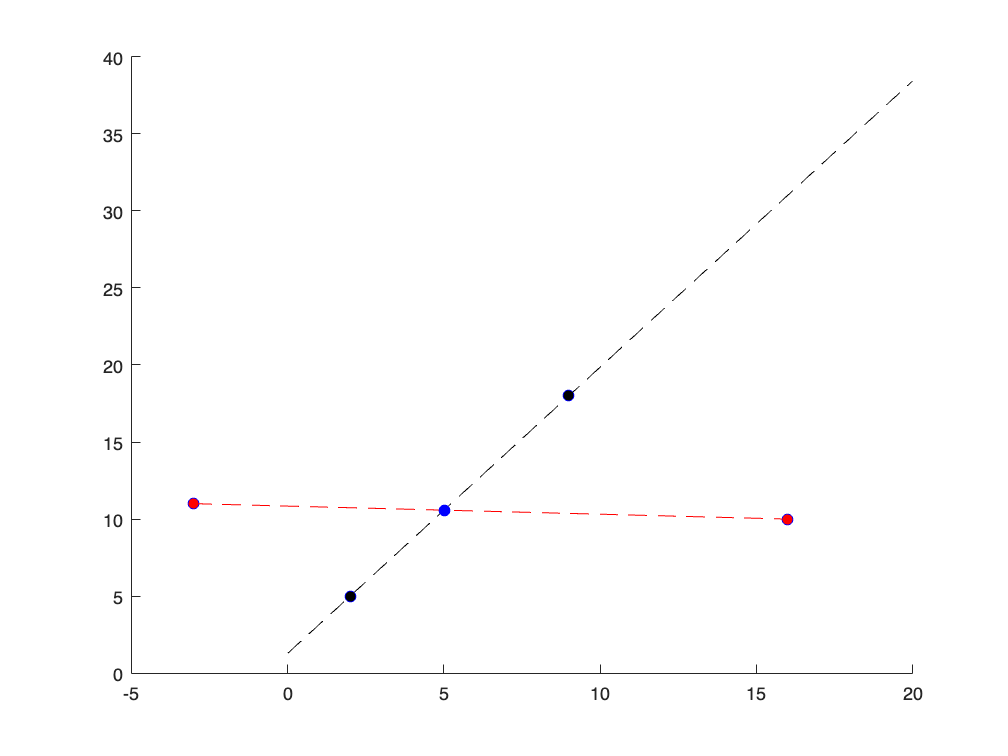

x_int = (b1*c2 - b2*c1) / (a1*b2 - a2*b1);
y_int = (a1*c2 - a2*c1) / (a1*b2 - a2*b1);

scatter(x_int, y_int, 'bo', 'markerfacecolor', 'blue')